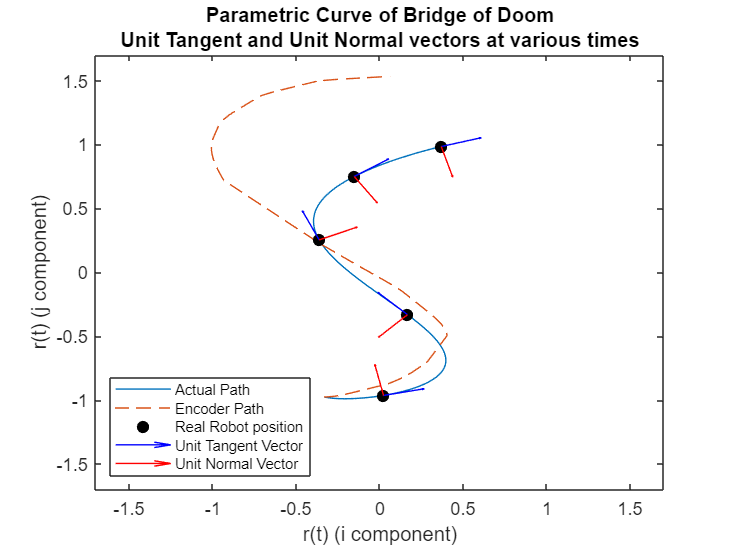

figure()
fplot(ri, rj, [0 16])
ylabel("r(t) (j component)")
xlabel("r(t) (i component)")
hold on;
title("Parametric Curve of Bridge of Doom"+ newline + "Unit Tangent and Unit Normal vectors at various times")
plot(x_pos_list, y_pos_list, "--")
hold on;

times = [2,7,10,13,16];
for time = times %plot T and N at specific times

    %Calculate starting point for tangent and unit vector
    i0 = double(subs(ri,{t},{time}));
    j0 = double(subs(rj,{t},{time}));
    plot(i0,j0,'.',MarkerSize=20,Color='black') %plot it as a point

    %Calculate end point for tangent vector
    Ti = tangent_vector(1); %isolate i component
    Tj = tangent_vector(2); %isolate j component
    Ti_cords = double(subs(Ti,{t},{time})); %calculate i component
    Tj_cords = double(subs(Tj,{t},{time})); %calculate j component

    %Calculate end point for normal vector
    Ni = normal_vector(1); %isolate i component
    Nj = normal_vector(2); %isolate j component
    Ni_cords = double(subs(Ni,{t},{time})); %calculate i component
    Nj_cords = double(subs(Nj,{t},{time})); %calculate j component
    
    quiver(i0,j0,Ti_cords,Tj_cords,0.25,Color='blue') %plot tangent vector
    quiver(i0,j0,Ni_cords,Nj_cords,0.25,Color='red') %plot normal vector
    legend('Actual Path','Encoder Path','Real Robot position','Unit Tangent Vector', 'Unit Normal Vector','fontsize',8,Location='southwest')
end
%set axis size
domain = 1.7;
axis([-domain domain -domain domain])
hold off;

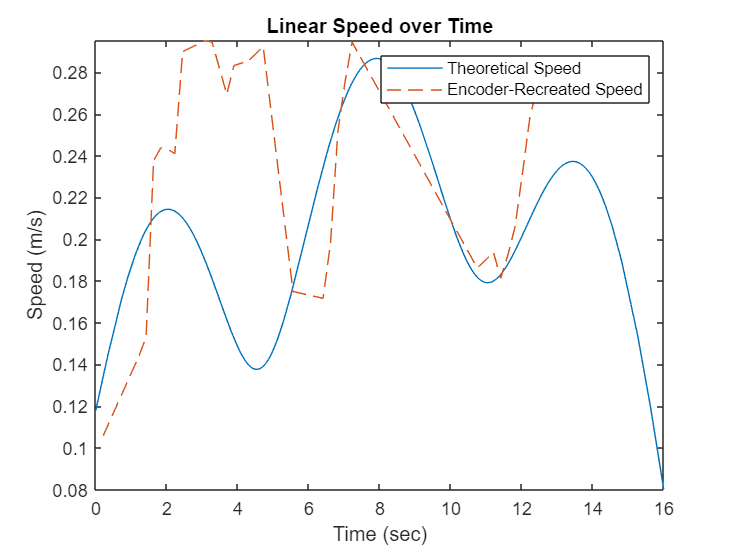

figure()
fplot(speed, [0 16])
ylabel("Speed (m/s)")
xlabel("Time (sec)")
title("Linear Speed over Time")
hold on
big_V_new = [];
time_new_V = [];
count = 1;
for i=1:length(big_V)
    if big_V(i) ~= 0 && big_V(i) <= 0.3
        big_V_new(count,1) = big_V(i);
        time_new_V(count,1) = time_old(i);
        count = count + 1;
    end
end

plot(time_new_V, big_V_new, "--")
legend("Theoretical Speed", "Encoder-Recreated Speed")

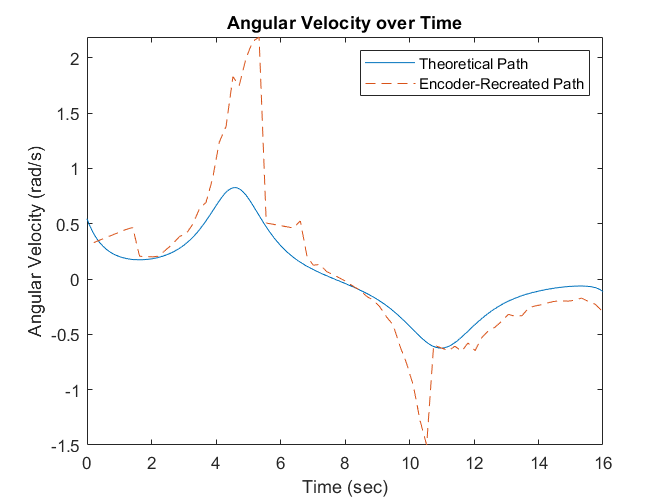

figure()
fplot(angular_velocity(3), [0 16])
ylabel("Angular Velocity (rad/s)")
xlabel("Time (sec)")
title("Angular Velocity over Time")
hold on


plot(time_new, ang_speed_new,"--");
legend("Theoretical Path", "Encoder-Recreated Path")

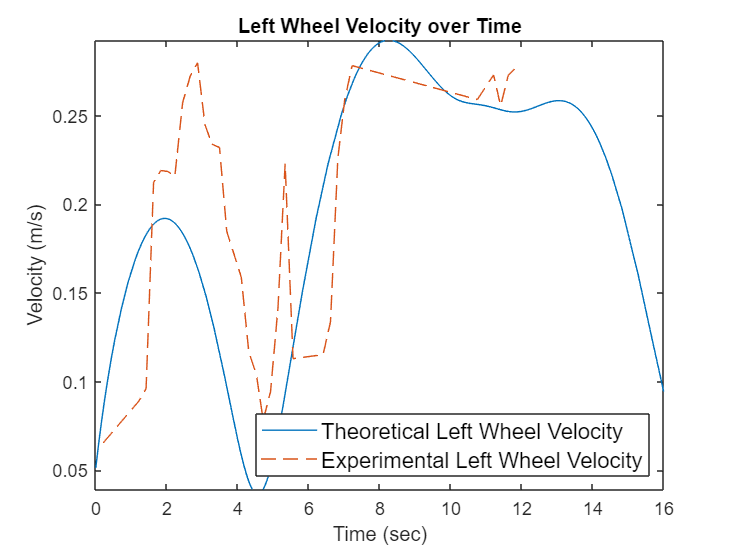

figure()
fplot(velocity_left(3), [0 16])
hold on
plot(time_new_left, left_new, "--")

ylabel("Velocity (m/s)")
xlabel("Time (sec)")
title("Left Wheel Velocity over Time")
legend("Theoretical Left Wheel Velocity","Experimental Left Wheel Velocity","fontsize", 12, "Location", "southeast")

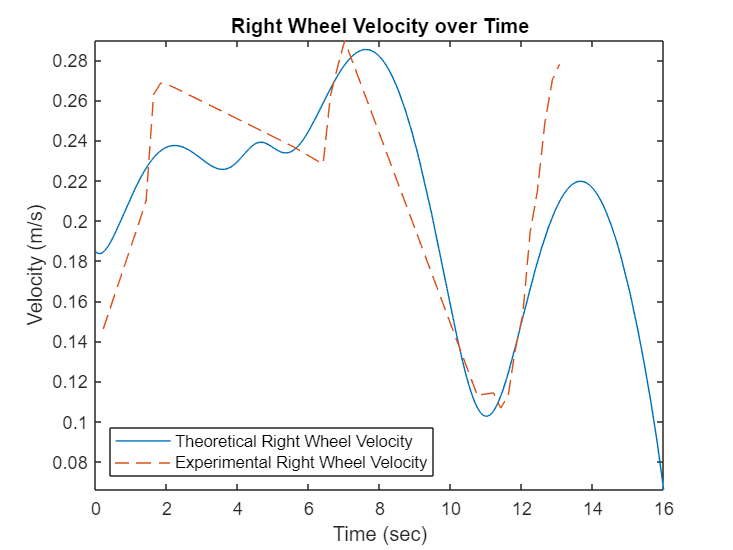

figure()
fplot(velocity_right(3), [0 16])
hold on
plot(time_new_right, right_new, "--")

ylabel("Velocity (m/s)")
xlabel("Time (sec)")
title("Right Wheel Velocity over Time")
legend("Theoretical Right Wheel Velocity","Experimental Right Wheel Velocity","Location", "southwest")